# eGEM CCLE hyperparameter optimization

## Summary

The goal of this module is to identify the best histone activity coefficient `epsilon` that maximize the variance between histone metabolic fluxes in the epigenome-scale metabolic model.

## Set Parameter distribution

First, let's create a random distribution of values using a log distribution ranging from 0 to 1. This will be used for the following modules.

clear all;

% Get a distribution of values
epsilon_dist = lognrnd(1E-3, 1, [1, 100000]);
epsilon_dist = 10.^-epsilon_dist;

% Show the distribution of values I will be sampling
histogram(epsilon_dist, 1000);

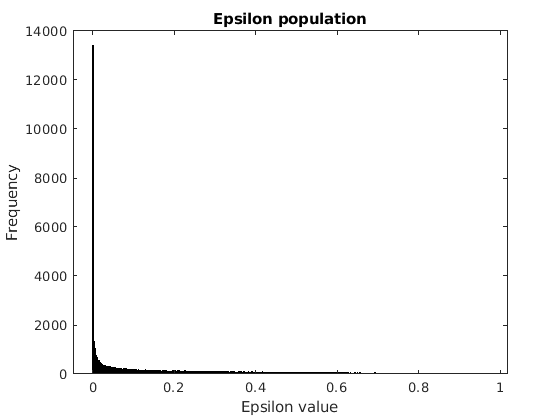

title('Epsilon population');
xlabel('Epsilon value');
ylabel('Frequency');
hold off;

## Set Model parameters

I will turn off some reactions that have been known to cause issues with the flux distribution, and will make the lower bound of the growth to be 0, while setting the biomass objective coefficient to 1. . 

initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.26.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load 07132020.mat; model = eGEM;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff) = 0; model.lb(posToTurnOff) = 0;
model.lb(ismember(model.rxns, 'biomass_objective')) = 0; % Change the lower bound of the biomass objective function to 0. 

This ensures that the primary objective function maximizes biomass production.

% Reset the primary objective function
model.c = zeros(size(model.c));
model.c(ismember(model.rxns, 'biomass_objective')) = 1;

Set the lower bound for methionine uptake

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -0.5;

## Make COBRA model into Gurobi form

Next, I'll create some variables in the COBRA structure that are needed to use the gurobi optimzer.

mediumMap = 'FINAL_MEDIUM_MAP.xlsx';
reactions_to_optimize = ["DM_KAC", "DM_KMe1", "DM_KMe2", "DM_KMe3"];
model.lb(ismember(model.rxns, reactions_to_optimize)) = 0;
model.rev(ismember(model.rxns, reactions_to_optimize)) = 0;

% Set up Gurobi model
model.A   = model.S;
model.obj = model.c;
model.rhs = model.b;

if (exist('model.csense','var')) && (~isempty(model.csense))
    model.sense = model.csense;
    model.sense(ismember(model.sense,'E')) = '=';
    model.sense(ismember(model.sense,'L')) = '<';
    model.sense(ismember(model.sense,'G')) = '>';
else
    model.sense = repmat('=', [size(model.S, 1), 1]);
end
model.vtype      = repmat('C', size(model.S, 2), 1);
model.modelsense = 'max';

params.outputflag          = 0;
params.Threads             = 4;
params.Seed                = 314;
params.NumericFocus        = 3;

Assign hyperparameters for the iMAT algorithm. Note that 

% Set up hyperparameters for the linear programming section
hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.kap2  = [];
hyperparams.pfba = true;

## Get histone activity coefficients from medium conditions

This module gets histone activity coefficients by selecting epsilon values for each demand reaction (27 demand reactions) that maximizes the variance across different medium conditions (44 medium conditions). We cache the data in a tensor.

First let's intialized some parameters, including medium conditions and getting demand reactions corresponding to histone markers.

% Optimize each demand reaction by a unique epsilon value across all medium
% conditions
[~, sheetNames] = xlsfinfo(mediumMap); 

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3777, 3780:3799];
dm_reactions = string(eGEM.rxns(pos));

Because MATLAB has been crashing on me, we will save the file iteratively in the for loop.

fileName = '~/Data/CBM/eGEM/epsilon/cached_epsilon.mat';
flux_cache = zeros([100, length(dm_reactions), length(sheetNames)]);
%save(fileName, 'flux_cache', '-v7.3')

Next, we'll sample 100 epsilon values for each reaction/medium condition pair. Note that this code takes awhile.

% This for-loop stores the data as a tensor. 
% The resulting tensor size will be (100 x 27 x 41)
% Sample 100 epsilon values
for i = 1:100
    epsilon(i, 1) = datasample(epsilon_dist, 1);
    
    % Set epsilon for each demand reaction
    for j = 1:length(dm_reactions)  
        tmp_mdl = model;
        tmp_mdl.c(ismember(tmp_mdl.rxns, dm_reactions(j))) = epsilon(i);
        tmp_mdl.obj(ismember(tmp_mdl.rxns, dm_reactions(j))) = epsilon(i);
        
        % Compute fluxes for each medium condition
        for k =  1:length(sheetNames)
            mediumModel = addMediumConstraints(tmp_mdl, sheetNames(k), mediumMap);
            soln = gurobi(mediumModel, params);
            histone_flux(j, k) = soln.x(ismember(tmp_mdl.rxns,  dm_reactions(j)));  
        end
        
        % Reset the objective coefficient
        tmp_mdl.c(ismember(tmp_mdl.rxns, dm_reactions(j))) = 0;
        tmp_mdl.obj(ismember(tmp_mdl.rxns, dm_reactions(j))) = 0;
    end
    
    % Cache the flux data for each epsilon-reaction pair across different
    % medium conditions
    flux_cache(i, :, :) = histone_flux;
    save(fileName, 'flux_cache', '-append');
end

This for look computes the variance for each reaction/medium pair for a given epsilon value.

% Compute the variance across all medium conditions for each demand
% reaction. This results in a matrix with the size of (100 x 27)
for i = 1:100
    for j = 1:length(dm_reactions)
        flux_var(i, j) = var(flux_cache(i, j, :));
    end
end

Let's visualize the variance matrix we just made. 

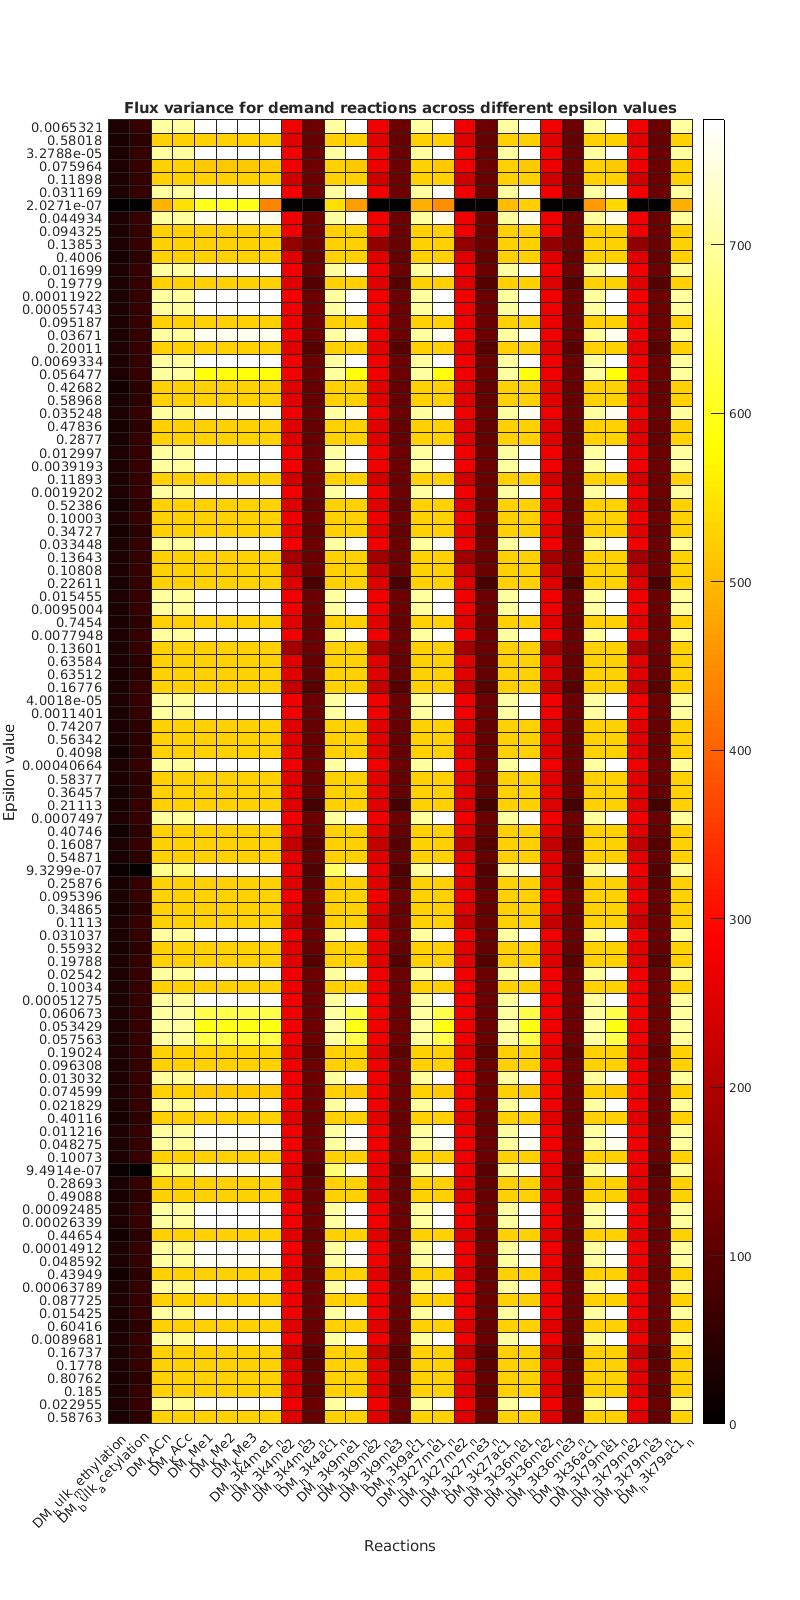

% Make heatmap 
heatmap(flux_var, ...
    'XData', dm_reactions, ...
    'YData', epsilon, ...
    'Colormap', hot, ...
    'ylabel', 'Epsilon value', ...
    'xlabel', 'Reactions', ...
    'title', 'Flux variance for demand reactions across different epsilon values', ...
    'FontSize', 10, ...
    'FontName', 'Helvetica');

set(gcf,'position',[0, 0, 800, 1600]);

Finally, for each demand reaction, grab the epsilon for a given demand reaction that maximized the variance across medium conditions. 

% Grab the epsilon value for a given demand reaction that corresponds to a
% specific demand reaction. This results in a vector of a size (1 x 27)
[~, idx] = max(flux_var);
final_epsilon = epsilon(idx, :);

Save the epsilon value corresponding to a given demand reaction

% Save Parameters
epsilon_array = [dm_reactions, final_epsilon];
save('~/Data/CBM/eGEM/epsilon/medium_epsilon.mat', 'epsilon_array');